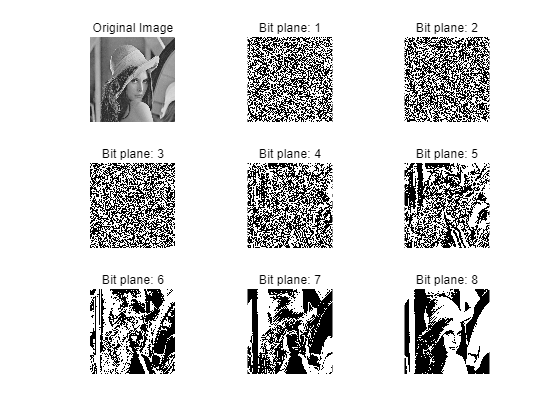

I = imread('images/lena_gray_256.tif');
H = 256;
W = 256;
bit_planes = zeros(8, H, W);
for k = 0:7
   for i = 1:H
       for j=1:W
           bit_planes(k+1,i,j)= bitand(I(i,j), 2.^k);
       end
   end
end
figure()
subplot(3, 3, 1);
imshow(I);
title('Original Image');

for k = 1:8
    subplot(3, 3, k+1);
    k_plane = squeeze(bit_planes(k, :, :));
    imshow(k_plane);
    title(sprintf('Bit plane: %d', k));
end

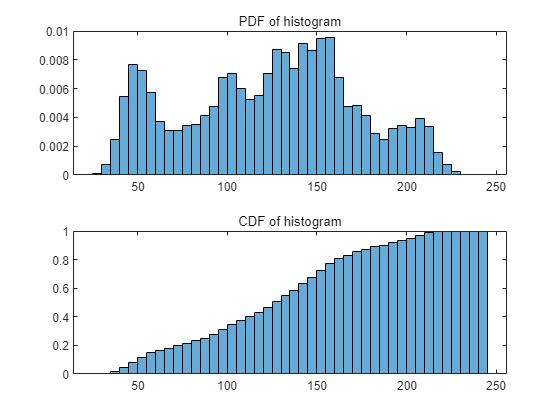


figure()
% Investigate the histogram 
subplot(2, 1, 1)
histogram(I, Normalization='pdf')
title('PDF of histogram')
subplot(2, 1, 2)
histogram(I, Normalization='cdf')
title('CDF of histogram')